%======== using Lalanne RotorDynamic Book finite element analysis - Direct Methode ========

n = 5;                   % Number of toltal Nodes
L_tot = 7; % [m]       % Total length of shaft
L = L_tot/n;             % Length Of each node
r_s = 0.2;              % shaft radius
rho_s = 7800;            % shaft density
E = 2e11;                % Young Modules

omega = 1;

% ============== SHAFT ================
pi = 3.1415

pi = 3.1415

S = pi*r_s^2             % Shaft Cross section Area

S = 0.1257

I = pi*r_s^4/4

I = 0.0013


M_ref = [156    0     0     -22*L   54    0     0      13*L;
         0      156   22*L   0      0     54   -13*L   0;
         0      22*L  4*L^2  0      0     13*L -3*L^2  0;
        -22*L   0     0      4*L^2 -13*L  0     0     -3*L^2;
         54     0     0     -13*L   156   0     0      22*L;
         0      54    13*L   0      0     156  -22*L   0;
         0     -13*L -3*L^2  0      0    -22*L  4*L^2  0;
         13*L   0     0     -3*L^2  22*L  0     0      4*L^2]*rho_s*S*L/420

M_ref =   509.6770         0         0 -100.6285  176.4266         0         0   59.4623
         0  509.6770  100.6285         0         0  176.4266  -59.4623         0
         0  100.6285   25.6145         0         0   59.4623  -19.2109         0
 -100.6285         0         0   25.6145  -59.4623         0         0  -19.2109
  176.4266         0         0  -59.4623  509.6770         0         0  100.6285
         0  176.4266   59.4623         0         0  509.6770 -100.6285         0
         0  -59.4623  -19.2109         0         0 -100.6285   25.6145         0
   59.4623         0         0  -19.2109  100.6285         0         0   25.6145



M_s = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*rho_s*I/(30*L)

M_s =     8.4013         0         0   -0.9801   -8.4013         0         0   -0.9801
         0    8.4013    0.9801         0         0   -8.4013    0.9801         0
         0    0.9801    1.8296         0         0   -0.9801   -0.4574         0
   -0.9801         0         0    1.8296    0.9801         0         0   -0.4574
   -8.4013         0         0    0.9801    8.4013         0         0    0.9801
         0   -8.4013   -0.9801         0         0    8.4013   -0.9801         0
         0    0.9801   -0.4574         0         0   -0.9801    1.8296         0
   -0.9801         0         0   -0.4574    0.9801         0         0    1.8296


     
M = zeros(n*4);

for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              M(1+k*4+i,1+k*4+j) = M(1+k*4+i,1+k*4+j) + M_ref(1+i,1+j) + M_s(1+i,1+j);
            end
        end
    end
end

% ============== DISK ================
D_d = 3.4;                                 % Disk Diameter
r_d = D_d/2;                               % Disk Radius
b_d = 0.3;                                % Disk Width
rho_d = 7800;                              % Disk Density
V_d = b_d*pi*D_d^2/4;                      % Disk Volume
M_D = rho_d*V_d;                           % Disk Mass
I_Dx = 0.25*M_D*r_d^2  +  (1/12)*M_D*b_d^2;  % Disk Inertia
I_Dy = 0.5*M_D*r_d^2;

n_d = 3;                                   % Number Of Node(s) Which Disk is Located
M_disk = [M_D;M_D;I_Dx;I_Dx].*eye(4);      % Disk Mass Matrix

k = n_d - 1

k = 2

if 1+k*4 < n*4
    for i = 0:3
        for j = 0:3
            M(1+k*4+i,1+k*4+j)= M(1+k*4+i,1+k*4+j) + M_disk(1+i,1+j);
        end
    end
end


% ============== SHAFT AND DISK DAMPING ================
C_disk = [0 0 0    0;
          0 0 0    0;
          0 0 0   -I_Dy;
          0 0 I_Dy 0]*omega;
      
C_ref = [0   -36  -3*L    0      0    36     -3*L    0;
         36   0    0     -3*L   -36   0       0     -3*L;
         3*L  0    0     -4*L^2 -3*L  0       0      L^2;
         0    3*L  4*L^2  0      0   -3*L    -L^2    0;
         0    36   3*L    0      0   -36      3*L    0;
        -36   0    0      3*L    36   0       0      3*L;
         3*L  0    0      L^2   -3*L  0       0     -4*L^2;
         0    3*L -L^2    0      0   -3*L     4*L^2  0]*(rho_s*I*omega/(15*L))

C_ref =          0  -16.8025   -1.9603         0         0   16.8025   -1.9603         0
   16.8025         0         0   -1.9603  -16.8025         0         0   -1.9603
    1.9603         0         0   -3.6592   -1.9603         0         0    0.9148
         0    1.9603    3.6592         0         0   -1.9603   -0.9148         0
         0   16.8025    1.9603         0         0  -16.8025    1.9603         0
  -16.8025         0         0    1.9603   16.8025         0         0    1.9603
    1.9603         0         0    0.9148   -1.9603         0         0   -3.6592
         0    1.9603   -0.9148         0         0   -1.9603    3.6592         0


  
C = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              C(1+k*4+i,1+k*4+j)=C(1+k*4+i,1+k*4+j)+C_ref(1+i,1+j);
            end
        end
    end
end      
      
k = n_d - 1

k = 2

if 1+k*4 < n*4
    for i = 0:3
        for j = 0:3
            C(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_disk(1+i,1+j);
        end
    end
end
% ============== SHAFT STIFFNESS ================
a = 0;
K_C = [12   0    0        -6*L      -12     0     0        -6*L;
       0    12   6*L       0         0     -12    6*L       0;
       0    6*L (4+a)*L^2  0         0     -6*L  (2-a)*L^2  0;
      -6*L  0    0        (4+a)*L^2  6*L    0     0        (2-a)*L^2;
      -12   0    0         6*L       12     0     0         6*L;
       0   -12  -6*L       0         0      12   -6*L       0;
       0    6*L (2-a)*L^2  0         0     -6*L  (4+a)*L^2  0;
      -6*L  0    0        (2-a)*L^2  6*L    0     0        (4+a)*L^2;]*E*I/((1+a)*L^3)

K_C = 	1.0e+09 *

    1.0991         0         0   -0.7693   -1.0991         0         0   -0.7693
         0    1.0991    0.7693         0         0   -1.0991    0.7693         0
         0    0.7693    0.7181         0         0   -0.7693    0.3590         0
   -0.7693         0         0    0.7181    0.7693         0         0    0.3590
   -1.0991         0         0    0.7693    1.0991         0         0    0.7693
         0   -1.0991   -0.7693         0         0    1.0991   -0.7693         0
         0    0.7693    0.3590         0         0   -0.7693    0.7181         0
   -0.7693         0         0    0.3590    0.7693         0         0    0.7181


  
F = 1;      
K_F = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*F/(30*L)

K_F =     0.8571         0         0   -0.1000   -0.8571         0         0   -0.1000
         0    0.8571    0.1000         0         0   -0.8571    0.1000         0
         0    0.1000    0.1867         0         0   -0.1000   -0.0467         0
   -0.1000         0         0    0.1867    0.1000         0         0   -0.0467
   -0.8571         0         0    0.1000    0.8571         0         0    0.1000
         0   -0.8571   -0.1000         0         0    0.8571   -0.1000         0
         0    0.1000   -0.0467         0         0   -0.1000    0.1867         0
   -0.1000         0         0   -0.0467    0.1000         0         0    0.1867



K = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              K(1+k*4+i,1+k*4+j)=K(1+k*4+i,1+k*4+j)+K_C(1+i,1+j)+K_F(1+i,1+j);
            end
        end
    end
end

%% ============== BEARINGS AND SEALS ================
kxx=8e7;
kxz=-1e7;
kzx=-6e7;
kzz=10e7;
cxx=8e3;
cxz=-3e3;
czx=-3e3;
czz=12e3;
K_bearing =-[kxx 0 kxz 0;
             0   0 0   0;
             kzx 0 kzz 0;
             0   0 0   0];

C_bearing =-[cxx 0 cxz 0;
             0   0 0   0;
             czx 0 czz 0;
             0   0 0   0];
         

n_bearings = [1 5];

for bearing = n_bearings
k = bearing - 1
if 1+k*4 < n*4
    for i = 0:3
        for j = 0:3
            K(1+k*4+i,1+k*4+j)= K(1+k*4+i,1+k*4+j) + K_bearing(1+i,1+j);
        end
    end
end
k = bearing - 1
if 1+k*4 < n*4
    for i = 0:3
        for j = 0:3
            C(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_bearing(1+i,1+j);
        end
    end
end
end

k = 0

k = 0

k = 4

k = 4

landa=M\K;
[Eivec,Eival] = eig(landa)

Eivec =    -0.0917    0.0917    0.0011    0.0010   -0.1492    0.1488    0.0038    0.0030   -0.2954    0.2871    0.0134    0.0104    0.3361    0.3329   -0.0602    0.3330    0.0833    0.2734    0.0540   -0.0000
    0.0075   -0.0078    0.0884    0.0885    0.0241   -0.0288    0.1442    0.1446    0.1131   -0.1314    0.2772    0.2774    0.3824    0.3926    0.4794   -0.4033   -0.5502   -0.3088   -0.5268   -0.4472
   -0.0549    0.0568   -0.6670   -0.6673   -0.0860    0.1052   -0.5802   -0.5798   -0.2032    0.2449   -0.6148   -0.6143   -0.4027   -0.3941   -0.4584    0.2253    0.3337    0.0539    0.4083   -0.0000
   -0.6685    0.6685    0.0091    0.0088   -0.5412    0.5376    0.0165    0.0138   -0.5461    0.5289    0.0345    0.0292    0.1958    0.2011   -0.0328    0.2823    0.0397    0.3370    0.0202   -0.0000
   -0.0259    0.0260    0.0004    0.0004   -0.0207    0.0199    0.0009    0.0008    0.2298   -0.2248   -0.0168   -0.0144    0.1002    0.0907   -0.0164   -0.0089    0.0331   -0.1589    0.02

Eival = 	1.0e+08 *

    1.4162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.4135         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.2576         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    1.2548         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.2123         0         0         0         0         0         0         0         0         0         0         0         0      

[Eival_sorted, ind] = sort(diag(Eival),'ascend');
Eivec_sorted = Eivec(:,ind);

for i = 1:n*4
    nat_freq(i) = sqrt(Eival_sorted(i))
end

nat_freq = 0.0000e+00 + 3.1629e+02i

nat_freq = 	1.0e+02 *

   0.0000 + 3.1629i   0.0000 + 3.0391i


nat_freq = 	1.0e+02 *

   0.0000 + 3.1629i   0.0000 + 3.0391i   0.0000 + 1.2160i


nat_freq = 	1.0e+02 *

   0.0000 + 3.1629i   0.0000 + 3.0391i   0.0000 + 1.2160i   0.0000 + 0.4930i


nat_freq = 	1.0e+02 *

   0.0000 + 3.1629i   0.0000 + 3.0391i   0.0000 + 1.2160i   0.0000 + 0.4930i   0.0000 + 0.0000i


nat_freq = 	1.0e+02 *

   0.0000 + 3.1629i   0.0000 + 3.0391i   0.0000 + 1.2160i   0.0000 + 0.4930i   0.0000 + 0.0000i   0.7221 + 0.0000i


nat_freq = 	1.0e+02 *

   0.0000 + 3.1629i   0.0000 + 3.0391i   0.0000 + 1.2160i   0.0000 + 0.4930i   0.0000 + 0.0000i   0.7221 + 0.0000i   2.3069 + 0.0000i


nat_freq = 	1.0e+02 *

   0.0000 + 3.1629i   0.0000 + 3.0391i   0.0000 + 1.2160i   0.0000 + 0.4930i   0.0000 + 0.0000i   0.7221 + 0.0000i   2.3069 + 0.0000i   2.3196 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.3163i   0.0000 + 0.3039i   0.0000 + 0.1216i   0.0000 + 0.0493i   0.0000 + 0.0000i   0.0722 + 0.0000i   0.2307 + 0.0000i   0.2320 + 0.0000i   1.2207 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.3163i   0.0000 + 0.3039i   0.0000 + 0.1216i   0.0000 + 0.0493i   0.0000 + 0.0000i   0.0722 + 0.0000i   0.2307 + 0.0000i   0.2320 + 0.0000i   1.2207 + 0.0000i   1.2341 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.3163i   0.0000 + 0.3039i   0.0000 + 0.1216i   0.0000 + 0.0493i   0.0000 + 0.0000i   0.0722 + 0.0000i   0.2307 + 0.0000i   0.2320 + 0.0000i   1.2207 + 0.0000i   1.2341 + 0.0000i   1.3887 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.3163i   0.0000 + 0.3039i   0.0000 + 0.1216i   0.0000 + 0.0493i   0.0000 + 0.0000i   0.0722 + 0.0000i   0.2307 + 0.0000i   0.2320 + 0.0000i   1.2207 + 0.0000i   1.2341 + 0.0000i   1.3887 + 0.0000i   1.4025 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.3163i   0.0000 + 0.3039i   0.0000 + 0.1216i   0.0000 + 0.0493i   0.0000 + 0.0000i   0.0722 + 0.0000i   0.2307 + 0.0000i   0.2320 + 0.0000i   1.2207 + 0.0000i   1.2341 + 0.0000i   1.3887 + 0.0000i   1.4025 + 0.0000i   4.3432 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.3163i   0.0000 + 0.3039i   0.0000 + 0.1216i   0.0000 + 0.0493i   0.0000 + 0.0000i   0.0722 + 0.0000i   0.2307 + 0.0000i   0.2320 + 0.0000i   1.2207 + 0.0000i   1.2341 + 0.0000i   1.3887 + 0.0000i   1.4025 + 0.0000i   4.3432 + 0.0000i   4.3647 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.3163i   0.0000 + 0.3039i   0.0000 + 0.1216i   0.0000 + 0.0493i   0.0000 + 0.0000i   0.0722 + 0.0000i   0.2307 + 0.0000i   0.2320 + 0.0000i   1.2207 + 0.0000i   1.2341 + 0.0000i   1.3887 + 0.0000i   1.4025 + 0.0000i   4.3432 + 0.0000i   4.3647 + 0.0000i   4.5863 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.3163i   0.0000 + 0.3039i   0.0000 + 0.1216i   0.0000 + 0.0493i   0.0000 + 0.0000i   0.0722 + 0.0000i   0.2307 + 0.0000i   0.2320 + 0.0000i   1.2207 + 0.0000i   1.2341 + 0.0000i   1.3887 + 0.0000i   1.4025 + 0.0000i   4.3432 + 0.0000i   4.3647 + 0.0000i   4.5863 + 0.0000i   4.6078 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 + 0.0316i   0.0000 + 0.0304i   0.0000 + 0.0122i   0.0000 + 0.0049i   0.0000 + 0.0000i   0.0072 + 0.0000i   0.0231 + 0.0000i   0.0232 + 0.0000i   0.1221 + 0.0000i   0.1234 + 0.0000i   0.1389 + 0.0000i   0.1402 + 0.0000i   0.4343 + 0.0000i   0.4365 + 0.0000i   0.4586 + 0.0000i   0.4608 + 0.0000i   1.1202 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 + 0.0316i   0.0000 + 0.0304i   0.0000 + 0.0122i   0.0000 + 0.0049i   0.0000 + 0.0000i   0.0072 + 0.0000i   0.0231 + 0.0000i   0.0232 + 0.0000i   0.1221 + 0.0000i   0.1234 + 0.0000i   0.1389 + 0.0000i   0.1402 + 0.0000i   0.4343 + 0.0000i   0.4365 + 0.0000i   0.4586 + 0.0000i   0.4608 + 0.0000i   1.1202 + 0.0000i   1.1214 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 + 0.0316i   0.0000 + 0.0304i   0.0000 + 0.0122i   0.0000 + 0.0049i   0.0000 + 0.0000i   0.0072 + 0.0000i   0.0231 + 0.0000i   0.0232 + 0.0000i   0.1221 + 0.0000i   0.1234 + 0.0000i   0.1389 + 0.0000i   0.1402 + 0.0000i   0.4343 + 0.0000i   0.4365 + 0.0000i   0.4586 + 0.0000i   0.4608 + 0.0000i   1.1202 + 0.0000i   1.1214 + 0.0000i   1.1889 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 + 0.0316i   0.0000 + 0.0304i   0.0000 + 0.0122i   0.0000 + 0.0049i   0.0000 + 0.0000i   0.0072 + 0.0000i   0.0231 + 0.0000i   0.0232 + 0.0000i   0.1221 + 0.0000i   0.1234 + 0.0000i   0.1389 + 0.0000i   0.1402 + 0.0000i   0.4343 + 0.0000i   0.4365 + 0.0000i   0.4586 + 0.0000i   0.4608 + 0.0000i   1.1202 + 0.0000i   1.1214 + 0.0000i   1.1889 + 0.0000i   1.1900 + 0.0000i



mode_shape = zeros(n*4);

for j = 1:n*4
    for i = 1:n*4
        mode_shape(i,j) = Eivec_sorted(i,j);
    end
end

u = zeros(n,n*4);
for j = 1:n*4
    for i=0:n-1
        u(i+1,j) = real(mode_shape(i*4 + 1,j));
    end
end
v = zeros(n,n*4);
for j = 1:n*4
    for i=0:n-1
        v(i+1,j) = real(mode_shape(i*4 + 2,j));
    end
end


M_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        M_diag_test(i,j)=transpose(mode_shape(:,i))*M*mode_shape(:,j);
    end
end

K_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        K_diag_test(i,j)=transpose(mode_shape(:,i))*K*mode_shape(:,j);
    end
end

C_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        C_diag_test(i,j)=transpose(mode_shape(:,i))*C*mode_shape(:,j);
    end
end

syms omega
assume(omega,'real')
C_diag_test = C_diag_test*omega

C = C*omega



syms lan  % lan = 1/r
A = [zeros(n*4)  M;M  C]

B = [M  zeros(n*4);zeros(n*4)  -K]

B = 	1.0e+09 *

    0.0000         0         0   -0.0000    0.0000         0         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000         0         0    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000         0         0    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0  

% X = [r*delta; delta]

eqn = det(A - (lan).*B)

vpa(eqn,2)

S = solve(vpa(eqn,2),lan)

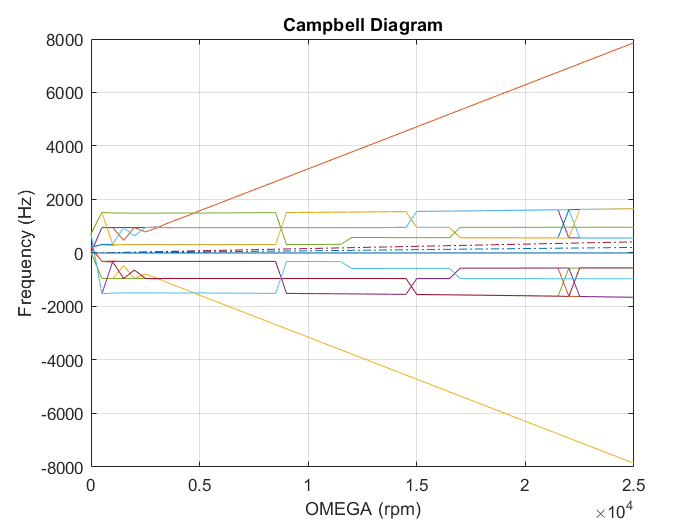

clear w
for omega= 0:500:25000   % in RPM
    S_new = subs(S,'omega',omega);
    landa = vpa(S_new);
    w(:,round(omega/500) + 1) = imag(1./landa);
    F = w./(2*pi);
end
% [eigvector, eigvalue]=eig(A - (lan).*B)
omega= 0:500:25000;
plot(omega,F(1:n*4,:))        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
grid on
hold on 
plot(omega,omega/60, '-.')
plot(omega,0.5*omega/60, '-.')
title('Campbell Diagram')
xlabel('OMEGA (rpm)')
ylabel('Frequency (Hz)')
hold off


t = 1:n

t =      1     2     3     4     5


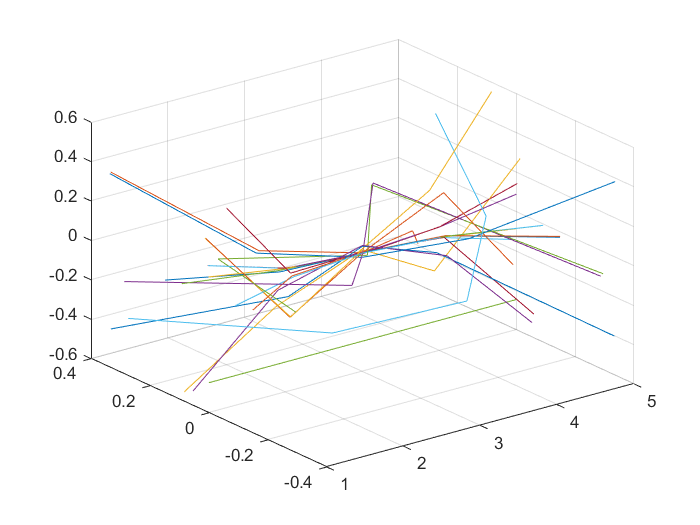

for i = 1:n*4
    plot3(t,u(:,i),v(:,i)); grid on;hold on
end
hold off


% for omega= 0:500:25000   % in RPM
%     A_new = subs(A,'omega',omega);
%     [eigvec_new, eigval_new]=eig(A_new)
% end

Error using sym/eig
Too many input arguments.


test_A = vpa(A,2);
test_B = vpa(B,2);

test_A = subs(test_A,'omega',25000);
[V_new,D_new]=eig(test_A*inv(test_B));
[D_new_sorted, ind] = sort(diag(D_new),'ascend');          % D_new_sorted is the same as landa(for getting r just use 1./D_new_sorted)
V_new_sorted = V_new(:,ind);                               % V_new_sorted is Delta(/_\)
smalldelta = 2*exp(real(1./D_new_sorted))*t*(real(V_new_sorted(:,1))*cos(imag(1./D_new_sorted)*t) - imag(V_new_sorted(:,1))*sin(imag(1./D_new_sorted)*t))

% delta is :
%    /\
%   /  \
%  /    \
% /______\